# **APPENDIX_A:  **Develop a Finite Element (FE) model of a Cantilever beam

## Background:

In this script

- We'll develop a **Finite Element model (FEM)** of a cantilever beam.

- We'll start with 4 elements

- We'll then consider 20-elements

- We'll then **simulate** the FE model (20 elements) subjected to applied dynamic loads (e.g.:  impact or Band Limited Noise).

- The "simulated" time series data will be **saved to EXCEL files** for analysis

- The file `tmp_Cantilver_.xlsx` is created by this script

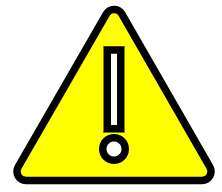  **ATTENTION:**  This script may take takes*** 5 minutes*** to run (Brads laptop)

- `Bradley Horton:  bhorton@mathworks.com`

## RESOURCES:

The following Appendix files are useful for some background knowledge:

- [`APPENDIX_00_Matrix_Algebra_Essentials_for_Modal.mlx`](matlab:  open bh_Modal.APPENDIX_00_Matrix_Algebra_Essentials_for_Modal)  

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

- [`APPENDIX_03_Signal_things.mlx `](matlab:  open  bh_Modal.APPENDIX_03_Signal_things)           

- [`APPENDIX_04_tf_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_04_tf_and_frf)

- [`APPENDIX_05_irf_and_fft_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_05_irf_and_fft_and_frf)

- [`APPENDIX_06_PHASE_PLOTS.mlx`](matlab:  open bh_Modal.APPENDIX_06_PHASE_PLOTS)

## Clear your Workspace

clear

# **FE model:**    The **4 element** Cantilever

Consider the Cantilever shown below

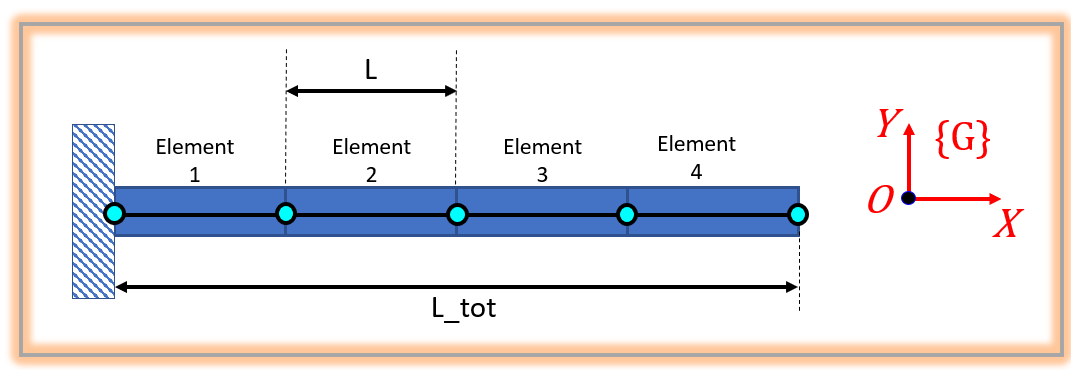

Let's parameterize the system geometry and element attributes.   Define the beam and Element lengths:

L_tot     = 8; % (m)
NUM_ELES  = 4;
NUM_NODES = 1 + NUM_ELES;
L         = L_tot/NUM_ELES;   % (m)

And parameterize the Element properties:

- A  :   cross sectional area

- E  :   Young's modulus

- I   :   2nd moment of area

A  =   8   * 6.4516e-4;      % (m^2)
E  =  29e3 * 6894.7573e3;    % (Pa ==N/m^2)
I  = 100   * 4.162314e-7;    % (m^4)

Specify the density of the material:

density = 7700;  % (kg/m^3)

# Analytical frequencies of vibration

For a Cantilever beam, the **analytical frequencies** of **Transverse (BENDING) vibration** can be derived and are tabulated in most introductory texts on Mechanical vibrations - e.g.: see

-    Rao, S., "Mechanical Vibrations, 2nd Edition", Addison Wesley, 1990

The first 4 Transverse natural frequencies are:

- See the function [`bh_cantil_analytic_modes()`](matlab:  open  bh_cantil_analytic_modes)

ANALYTIC_Bending_freqs_tab = bh_cantil_analytic_modes(A, E, I, L_tot, density);

So what are they ?

display(ANALYTIC_Bending_freqs_tab)

ANALYTIC_Bending_freqs_tab = 4×2 table
    fn_Hz     wn_radpersec
    ______    ____________

    4.0012        25.14   
    25.075       157.55   
    70.211       441.15   
    137.59       864.48   

	Get insights using Copilot


# Define the **LOCAL** element Stiffness and Mass matrices:

#    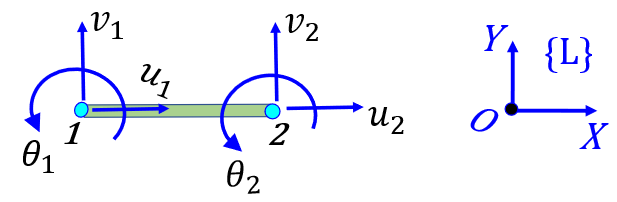 

The local stiffness matrix for the frame element can be defined as:   $[\thinspace ^LK_{ele} \thinspace] = F(A,E,I,L)$, where:

- A : is the cross sectional area  $\left(m^2 \right)$

- E : is Young's modulus $\left(N/m^2 \right)$

- I : is the 2nd moment of Area $\left(m^4 \right)$

- L : is the element's length $\left(m\right)$

See the SUBfunction `LOC_get_Kele_Mele_LOCAL()`

[K_ele, M_ele] = LOC_get_Kele_Mele_LOCAL(A, E, I, L, density);

# Define the **global SYSTEM** matrices

Our FULL system DoF vector is:

- 
$$D = \pmatrix{
u_1 ,  &
v_1 , &
\theta_1, &
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5
}^T$$
  

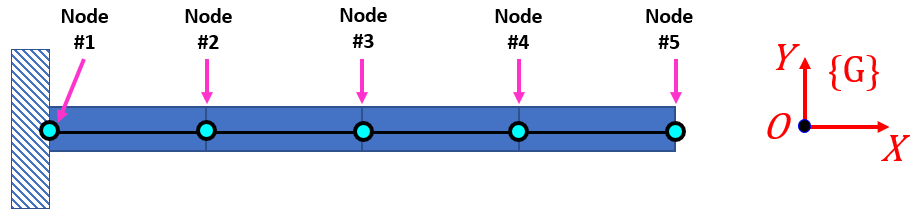     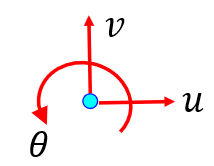

Define the FULL system stiffness matrix $\bm{K}$ and the FULL system mass matrix $\bm{M}$:

K_full = zeros(3*NUM_NODES, 3*NUM_NODES);
M_full = zeros(3*NUM_NODES, 3*NUM_NODES);

#### Assemble the FULL system STIFFNESS matrix:      `K_full  and M_full`

Now start building up the stiffness matrix by adding each local element stiffness matrix into the FULL system matrix, ie:

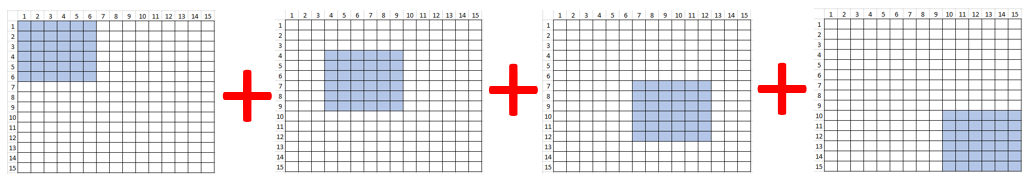

**ELEMENT #1: **    **The DoF are** $ \pmatrix{
u_1 ,  &
v_1 , &
\theta_1, &
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  \cr
1 & 2& 3& 4& 5& 6& .& .& .& .& .& .& .& .& .
}$  

             inds  = 1:6;
K_full(inds, inds) = K_full(inds, inds) + K_ele;
M_full(inds, inds) = M_full(inds, inds) + M_ele;

**ELEMENT #2: **    **The DoF are** $ \pmatrix{
u_1 ,  &
v_1 , &
\theta_1, &
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  \cr
. & .& .& 4& 5& 6& 7& 8& 9& .& .& .& .& .& .
}$

             inds  = 4:9;
K_full(inds, inds) = K_full(inds, inds) + K_ele;
M_full(inds, inds) = M_full(inds, inds) + M_ele;

**ELEMENT #3: **    **The DoF are** $ \pmatrix{
u_1 ,  &
v_1 , &
\theta_1, &
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  \cr
. & .& .& .& .& .& 7& 8& 9& 10& 11& 12& .& .& .
}$

             inds  = 7:12;
K_full(inds, inds) = K_full(inds, inds) + K_ele;
M_full(inds, inds) = M_full(inds, inds) + M_ele;

**ELEMENT #4: **    **The DoF are** $ \pmatrix{
u_1 ,  &
v_1 , &
\theta_1, &
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  \cr
. & .& .& .& .& .& .& .& .& 10& 11& 12& 13& 14& 15
}$

             inds  = 10:15;
K_full(inds, inds) = K_full(inds, inds) + K_ele;
M_full(inds, inds) = M_full(inds, inds) + M_ele;

What does the stiffness matrix look like ?

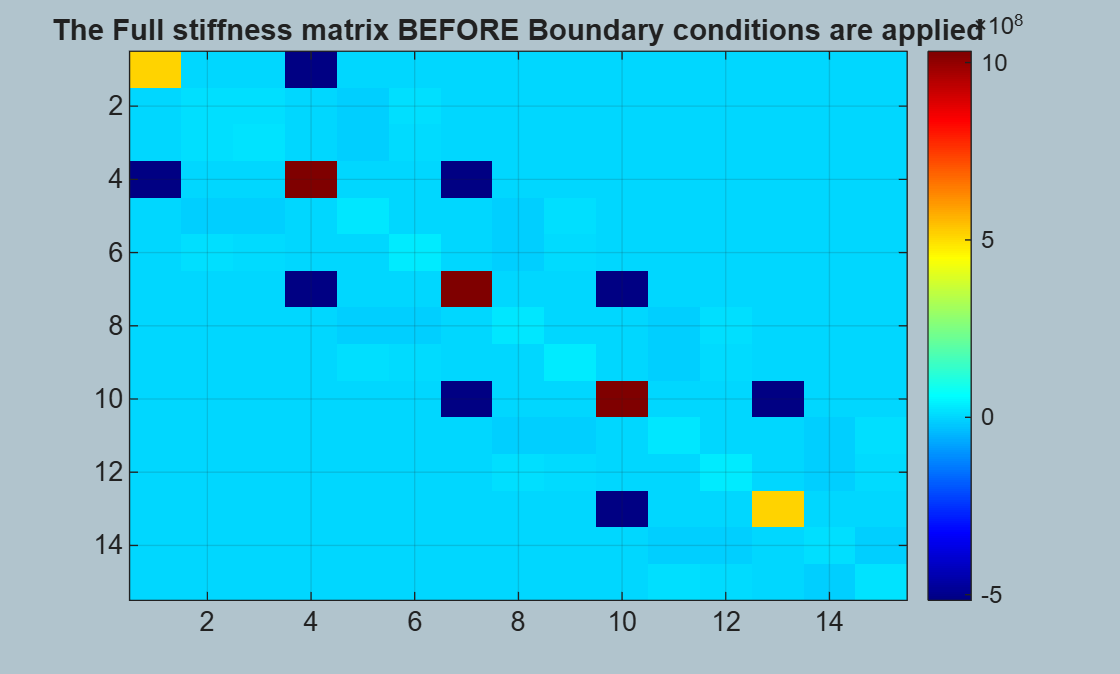

figure;
   imagesc(K_full); 
     colormap('jet')
     colorbar;
     grid('on')
     title("The Full stiffness matrix BEFORE Boundary conditions are applied")

# Apply the Boundary conditions:

     

Our cantilever boundary condition is:

- 
$$\left\lbrack \begin{array}{ccc}
u_1  & v_1  & \theta_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack$$


Create new Stiffness and Force matrices where the boundary condition has been applied, ie: ignore the first 3 rows and columns of ***K*** and ***M***

K_red = K_full(4:end, 4:end);
M_red = M_full(4:end, 4:end);

So the remaining dof are:

-  
$$ \pmatrix{
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  
}$$


# Modal Analysis

Before we simulate(aka solve) our derived equations of motion, let's do a MODAL analysis of the system.  Consider the **UNdamped** homogeneous system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

And let's look for a harmonic solution of the form:

- 
$$X\left(t\right)=\;\;\;\;\;\;v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{X} \left(t\right)=\;\;\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp X\left(t\right)$$


- 
$$\ddot{X} \left(t\right)=\;\;\;-1\ldotp \omega^2 \ldotp X\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(t\right)\;=\;0$$


- 
$$K\ldotp X\left(t\right)=M\ldotp X\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp X\left(t\right)=\omega^2 \ldotp X\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

The last equation is the **classic Eigenvalue problem**.  So let's solve this in MATLAB using the [`eig()`](matlab: doc eig) function:

tmp_A        = inv(M_red) * K_red;
[eVec, eVal] = eig(tmp_A)

eVec =    -0.2420   -0.5843   -0.5843   -0.2420   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0110   -0.0607    0.0196   -0.0948    0.3303   -0.3900    0.2704   -0.0759
    0.0000   -0.0000    0.0000   -0.0000   -0.0561   -0.4151    0.5254    0.4120   -0.1898   -0.1068    0.1852   -0.0710
    0.4472    0.4472   -0.4472   -0.4472   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0168    0.0210   -0.1391    0.0130   -0.3408   -0.0118    0.4626   -0.2647
    0.0000   -0.0000    0.0000   -0.0000   -0.1577   -0.5790   -0.0873   -0.4694   -0.0110    0.3727   -0.0367   -0.1134
   -0.5843    0.2420    0.2420   -0.5843   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0313    0.0844    0.0691    0.0616    0.2938    0.3136    0.0876   -0.5129
    0.0000   -0.0000    0

eVal = 1.0e+07 *

    6.9636         0         0         0         0         0         0         0         0         0         0         0
         0    3.3300         0         0         0         0         0         0         0         0         0         0
         0         0    1.0092         0         0         0         0         0         0         0         0         0
         0         0         0    0.1014         0         0         0         0         0         0         0         0
         0         0         0         0    4.6438         0         0         0         0         0         0         0
         0         0         0         0         0    1.7249         0         0         0         0         0         0
         0         0         0         0         0         0    0.6863         0         0         0         0         0
         0         0         0         0         0         0         0    0.2661         0         0         0         0
         0    

whos eVec   eVal

  Name       Size            Bytes  Class     Attributes

  eVal      12x12             1152  double              
  eVec      12x12             1152  double              



**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec    = eVec(:, ind);
eVal    = eVal(:, ind);

Since $M=M^T$  and  $K=K^T$ then let's **normalize** the eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


tmp         = eVec.' * M_red * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_red * eVec_PHI;

Confirm the eigenvector normalizations with a plot

figure;
    heatmap(Im_mat, "Colormap", jet(20) );
        title("V^T . M . V")

And the above eigenvector scaling should also give us:

- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


w2_mat      = eVec_PHI.' * K_red * eVec_PHI;

figure;
    heatmap(w2_mat, "Colormap", jet(50) );
        title("V^T . K . V")

#### Great, so let's summarise what we have. 

Our UNdamped Natural frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( diag(w2_mat) );
w_table = array2table( [w_list, w_list/(2*pi)], "VariableNames", {'w_radpersec', 'f_Hz'}  )

w_table = 12×2 table
    w_radpersec     f_Hz 
    ___________    ______

      25.141       4.0014
      157.74       25.104
      444.57       70.755
      877.03       139.58
        1007       160.27
      1631.2       259.62
      2619.8       416.95
      3176.7       505.59
      4153.2       661.01
      5770.6       918.42
      6814.6       1084.6
      8344.8       1328.1

	Get insights using Copilot


## And Let's plot some Mode shapes

Recall the DOF vector

-  
$$ \pmatrix{
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5  
}$$


So we're interested in plotting the $v_i$ dof

- **NOTE:**  with only 4 elements this is NOT going to be a pretty looking plot

modes_v = eVec_PHI(2:3:end, :);        % so grab v dof only
modes_v = [zeros(1,size(modes_v,2));   % make v at WALL node ZERO
           modes_v ];

x = [0:NUM_ELES]*L;

MODE_ID = 2;

figure
    plot(x, modes_v(:,MODE_ID), "-ro");
        grid on;  
        xlabel("x (m)")
        title("MODE shape ID = "+MODE_ID)

# **FE model:**    The **20 element** Cantilever

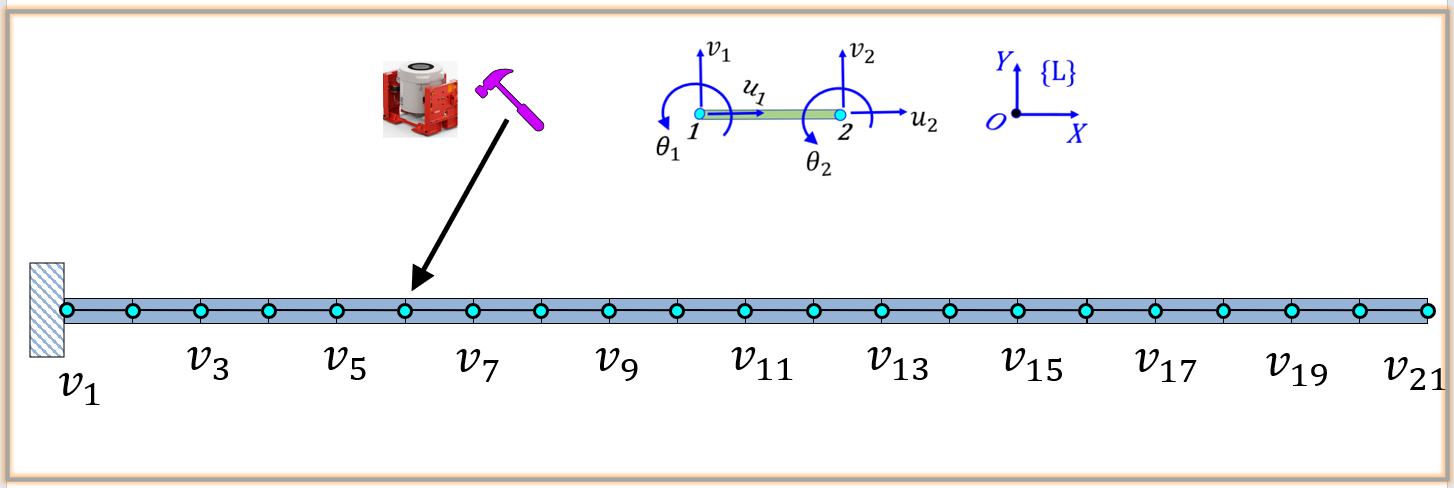

In the above example we only had 4 elements.  So it was simple to manually assemble the FULL system stiffness matrix.  But what if we had 100's, 1000's ... millions of elements ? Clearly we need a way of automating the assembly of the system stiffness matrix.  The `for loop` construct is perfect for doing this.  

## Define the **LOCAL** element Stiffness and Mass matrices:

So specify the Number of elements:

NUM_ELES  = 20;
NUM_NODES = NUM_ELES + 1;
L         = L_tot/NUM_ELES;

#    

The local stiffness matrix for the frame element can be defined as:   $[\thinspace ^LK_{ele} \thinspace] = F(A,E,I,L)$, where:

- A : is the cross sectional area  $\left(m^2 \right)$

- E : is Young's modulus $\left(N/m^2 \right)$

- I : is the 2nd moment of Area $\left(m^4 \right)$

- L : is the element's length $\left(m\right)$

See the SUBfunction `LOC_get_Kele_Mele_LOCAL()`

[K_ele, M_ele] = LOC_get_Kele_Mele_LOCAL(A, E, I, L, density);

Prepare the FULL system matrices

K_full   = zeros(3*NUM_NODES, 3*NUM_NODES);
M_full   = zeros(3*NUM_NODES, 3*NUM_NODES);

Here's how you could then apply this concept to the cantilever represented by many(many) elements:

% assemble the FULL system stiffness matrix
for ee=1:NUM_ELES
    
                inds  = (1:6) + (ee-1)*3;
   K_full(inds, inds) = K_full(inds, inds) + K_ele;
   M_full(inds, inds) = M_full(inds, inds) + M_ele;   

end

## Apply the Boundary Conditions

% apply the boundary conditions
K_red = K_full(4:end, 4:end);
M_red = M_full(4:end, 4:end);

## Perform Modal Analysis

tmp_A        = inv(M_red) * K_red;
[eVec, eVal] = eig(tmp_A);
whos eVec   eVal

  Name       Size            Bytes  Class     Attributes

  eVal      60x60            28800  double              
  eVec      60x60            28800  double              



**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec    = eVec(:, ind);
eVal    = eVal(:, ind);

Since $M=M^T$  and  $K=K^T$ then let's normalise the eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


tmp         = eVec.' * M_red * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_red * eVec_PHI;

Confirm the eigenvector normalizations with a plot

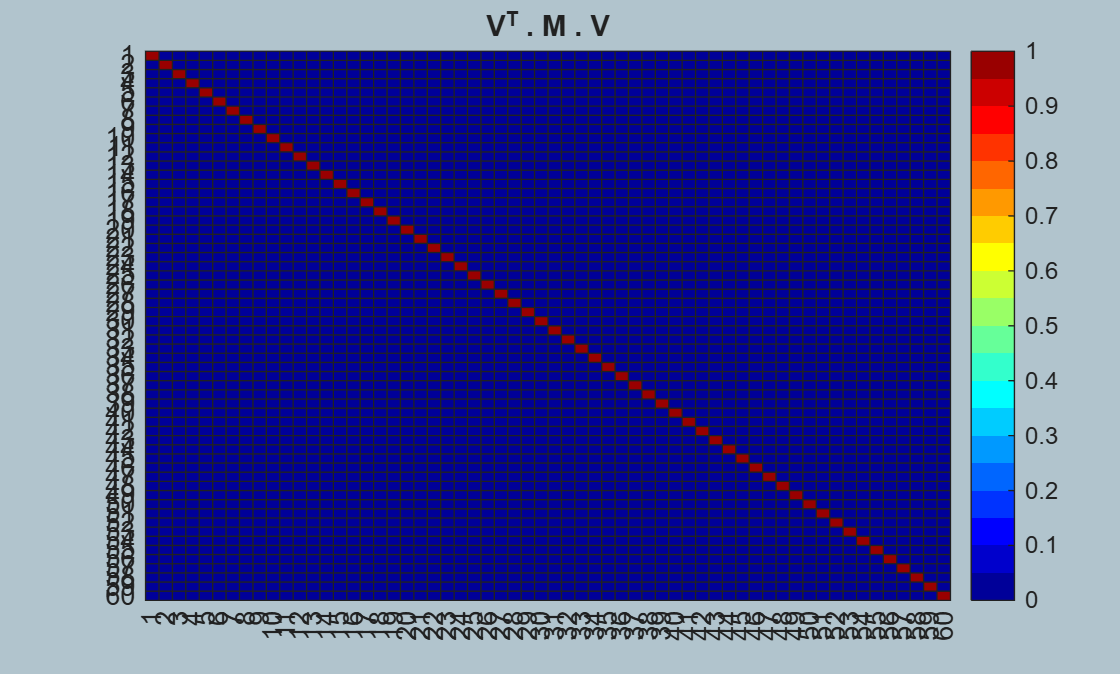

figure;
    heatmap(Im_mat, "Colormap", jet(20) );
        title("V^T . M . V")

And the above eigenvector scaling should also give us:

- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


w2_mat      = eVec_PHI.' * K_red * eVec_PHI;

#### Great, so let's summarise what we have. 

Our UNdamped frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( diag(w2_mat) );
w_table = array2table( [w_list, w_list/(2*pi)], "VariableNames", {'w_radpersec', 'f_Hz'}  )

w_table = 60×2 table
    w_radpersec     f_Hz 
    ___________    ______

       25.14       4.0012
      157.55       25.075
      441.16       70.213
      864.53       137.59
      1000.8       159.28
      1429.3       227.48
      2135.5       339.88
      2983.7       474.88
      3008.6       478.84
      3974.6       632.58
        5035       801.35
      5109.2       813.16
      6389.1       1016.9
      7092.4       1128.8
      7816.5         1244
      9193.5       1463.2

	Get insights using Copilot


## And Let's plot some Mode shapes

Recall the DOF vector

-  
$$ \pmatrix{
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5,  \quad .... \quad etc
}$$


So we're interested in plotting the $v_i$ dof

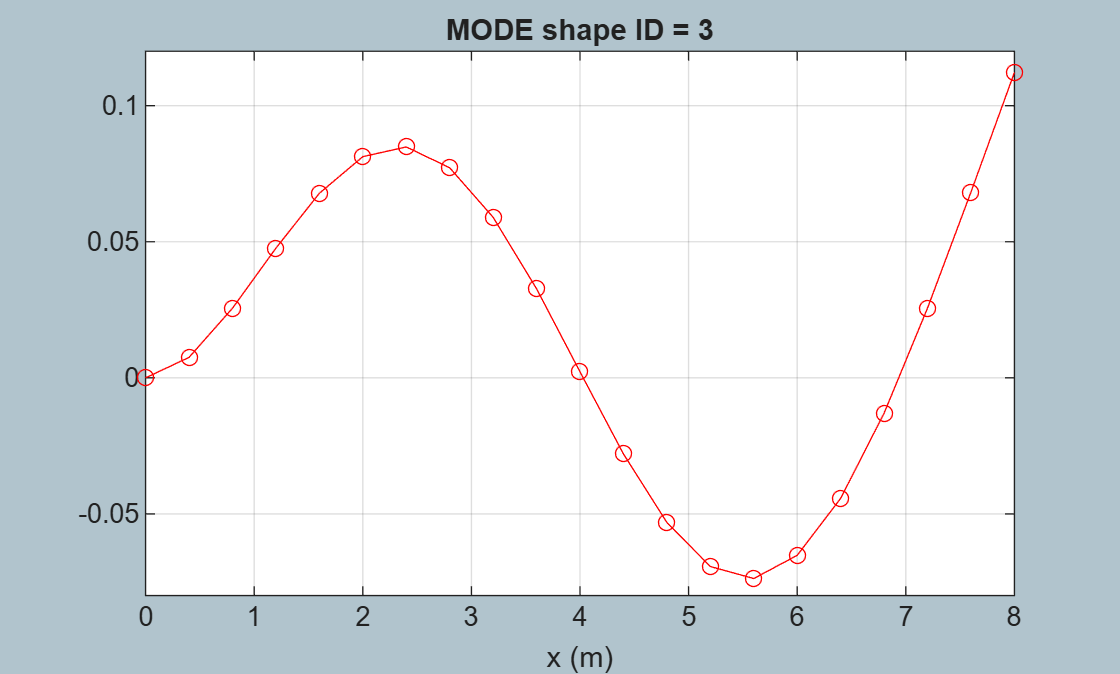

modes_v = eVec_PHI(2:3:end, :);
modes_v = [zeros(1,size(modes_v,2));
           modes_v ];

x = [0:NUM_ELES]*L;

MODE_ID = 3;

figure
    plot(x, modes_v(:,MODE_ID), "-ro");
        grid on;  
        xlabel("x (m)")
        title("MODE shape ID = "+MODE_ID)

Some bookkeeping

DOF_LABEL_STR = ["u_","v_","th_"];
DOF_LABEL_STR = repmat(DOF_LABEL_STR, 1, NUM_NODES);
for kk=1:NUM_NODES    
  
    ind = (kk-1)*3;
    DOF_LABEL_STR(ind+1) = DOF_LABEL_STR(ind+1) + kk;
    DOF_LABEL_STR(ind+2) = DOF_LABEL_STR(ind+2) + kk;
    DOF_LABEL_STR(ind+3) = DOF_LABEL_STR(ind+3) + kk;
end

Remove the Boundary Node dof - they are NOT present in the M,C,K matrices

DOF_LABEL_STR(1:3) = []

DOF_LABEL_STR = 1×60 string array
    "u_2"    "v_2"    "th_2"    "u_3"    "v_3"    "th_3"    "u_4"    "v_4"    "th_4"    "u_5"    "v_5"    "th_5"    "u_6"    "v_6"    "th_6"    "u_7"    "v_7"    "th_7"    "u_8"    "v_8"    "th_8"    "u_9"    "v_9"    "th_9"    "u_10"    "v_10"    "th_10"    "u_11"    "v_11"    "th_11"    "u_12"    "v_12"    "th_12"    "u_13"    "v_13"    "th_13"    "u_14"    "v_14"    "th_14"    "u_15"    "v_15"    "th_15"    "u_16"    "v_16"    "th_16"    "u_17"    "v_17"    "th_17"    "u_18"    "v_18"    "th_18"    "u_19"    "v_19"    "th_19"    "u_20"    "v_20"    "th_20"    "u_21"    "v_21"    "th_21"


Also, extract the Transverse dof  - we'll use these later

tmp_tf       = contains(DOF_LABEL_STR, "v_");
v_dof_labels = DOF_LABEL_STR(tmp_tf)

v_dof_labels = 1×20 string array
    "v_2"    "v_3"    "v_4"    "v_5"    "v_6"    "v_7"    "v_8"    "v_9"    "v_10"    "v_11"    "v_12"    "v_13"    "v_14"    "v_15"    "v_16"    "v_17"    "v_18"    "v_19"    "v_20"    "v_21"


# Define damping Matrix

We'll assume a Proportionally damped system, i.e.: a system where the UNdamped modes can also diagonalize the damping matrix

- 
$${\left\lbrack 2\ldotp \zeta \ldotp \omega_n \right\rbrack }_{\mathrm{diag}} =\;\;\Phi^T \ldotp C\ldotp \Phi$$


So let's specify that we want a certain set of damping ratios, and then reconstruct the Damping matrix from that:

desired_damp_ratios = 0.1*ones(size(eVec_PHI,1), 1);
desired_damp_ratios(1:4) = [0.001, 0.002, 0.003, 0.004]

desired_damp_ratios =     0.0010
    0.0020
    0.0030
    0.0040
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000



tmp_LHS = 2 * sqrt(diag(w2_mat)) .* desired_damp_ratios;
tmp_LHS = diag(tmp_LHS);

C_red = inv(eVec_PHI.') * tmp_LHS * inv(eVec_PHI);

### Summarise our MODAL frequencies and damping:

w_table           = array2table( [w_list, w_list/(2*pi), desired_damp_ratios], ...
                                 "VariableNames", {'w_radpersec', 'f_Hz', 'zeta'}  )

w_table = 60×3 table
    w_radpersec     f_Hz     zeta 
    ___________    ______    _____

       25.14       4.0012    0.001
      157.55       25.075    0.002
      441.16       70.213    0.003
      864.53       137.59    0.004
      1000.8       159.28      0.1
      1429.3       227.48      0.1
      2135.5       339.88      0.1
      2983.7       474.88      0.1
      3008.6       478.84      0.1
      3974.6       632.58      0.1
        5035       801.35      0.1
      5109.2       813.16      0.1
      6389.1       1016.9      0.1
      7092.4       1128.8      0.1
      7816.5         1244      0.1
      9193.5       1463.2      0.1

	Get insights using Copilot


# Stimulate and Simulate the system

A classic N-dof Mechanical system can be expressed as:

- $M \ddot{X} + C\dot{X} + KX = F$   where   $X \in R^{n\times1}$

Which can also be expressed as the $1^{\mathrm{st}}$ order system :

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$. \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  $\dot{Z} = A . Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

% Define your INITIAL conditions
z_init = zeros(2*size(M_red,1), 1);

n      = size(M_red, 1); 
N      = 2*n;
I_n    = eye(n);
O_n    = zeros(n);
inv_M  = inv(M_red);

A_mat  = [ -1*inv_M*C_red,   -1*inv_M*K_red;
                      I_n,    O_n];

### Define Possible Excitation sequences

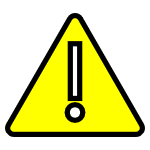 **NOTE: **We will configure each Excitation sequence with it's own unique Sampling Frequency and test duration

#### Define an IMPULSE type force

Apply the force at ***NODE 6***

THE_DT      = 1/2000;
THE_T_LIST  = [0:THE_DT:10];  % [0:THE_DT:10];

hammer.Name = "hammer";
hammer.dt = THE_DT;
hammer.t = THE_T_LIST;
hammer.f = zeros(size(hammer.t));
hammer.pulse_width_in_samples  = 5;
hammer.pulse_width_in_seconds      = hammer.pulse_width_in_samples * THE_DT;
hammer.pulse_bandwidth_Hz_BESTCASE = 1/hammer.pulse_width_in_seconds;
tmp_ind = 1:hammer.pulse_width_in_samples;
hammer.f(tmp_ind) = 1e4;
hammer.DOF_ID     = find(DOF_LABEL_STR=="v_6");
hammer.Fh         = @(t) LOC_F_exciter(t, n, hammer);

#### Define a Band Limited Noise (BLN) type force

Apply the force at ***NODE 6***

THE_DT      = 1/1000;
THE_T_LIST  = [0:THE_DT:60];  

BLN_specs.Low_pass_filter_PASS_freq_Hz = 200;
BLN_specs.Low_pass_filter_STOP_freq_Hz = 300;
BLN_specs.Fs_Hz                        = 1/THE_DT;
BLN_specs.Mag_of_Force                 = 1e4;  % the standard deviation of the random signal

obj_BLN   = bh_Modal.CLS_BLN( BLN_specs.Low_pass_filter_PASS_freq_Hz, ...
                              BLN_specs.Low_pass_filter_STOP_freq_Hz, BLN_specs.Fs_Hz);  

obj_BLN   = obj_BLN.create_sig( length(THE_T_LIST),  ...
                                BLN_specs.Mag_of_Force );
shaker.Name      = "shaker";
shaker.dt        = THE_DT;
shaker.t         = THE_T_LIST;
shaker.f         = [obj_BLN.y_col]';
shaker.DOF_ID    = find(DOF_LABEL_STR=="v_6");
shaker.Fh        = @(t) LOC_F_exciter(t, n, shaker);

#### Define a Chirp (swept frequency) type force

Apply the force at ***NODE 6***

THE_DT               = 1/1000;
THE_T_LIST           = [0:THE_DT:60];     % [0:THE_DT:10];

CHIRP_specs.f0       = 0;                 % (Hz)
CHIRP_specs.t1       = THE_T_LIST(end);   % (secs)
CHIRP_specs.f1       = 80;                % (Hz)
CHIRP_specs.MAG      = 5000;              % (N)

chirp_exci.Name      = "chirp";
chirp_exci.dt        = THE_DT;
chirp_exci.t         = THE_T_LIST;
chirp_exci.f         = CHIRP_specs.MAG * ...
                        chirp(THE_T_LIST, CHIRP_specs.f0, CHIRP_specs.t1, CHIRP_specs.f1);
chirp_exci.DOF_ID    = find(DOF_LABEL_STR=="v_6");
chirp_exci.Fh        = @(t) LOC_F_exciter(t, n, chirp_exci);

### So which Exciter do you want ?

% THE_EXCITER = chirp_exci;
THE_EXCITER = shaker;
% THE_EXCITER = hammer;

Echo and plot the exciter being used

THE_EXCITER

THE_EXCITER = struct with fields:
      Name: "shaker"
        dt: 1.0000e-03
         t: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 … ] (1×60001 double)
         f: [3.0842 33.8517 154.1500 416.0325 741.6034 870.6243 539.2462 -210.7918 -931.1685 -1.0291e+03 -156.4176 1.5669e+03 3.5333e+03 4.8206e+03 4.6684e+03 3.1213e+03 1.1948e+03 113.2866 239.9224 898.8186 1.3353e+03 1.5929e+03 … ] (1×60001 double)
    DOF_ID: 14
        Fh: @(t)LOC_F_exciter(t,n,shaker)


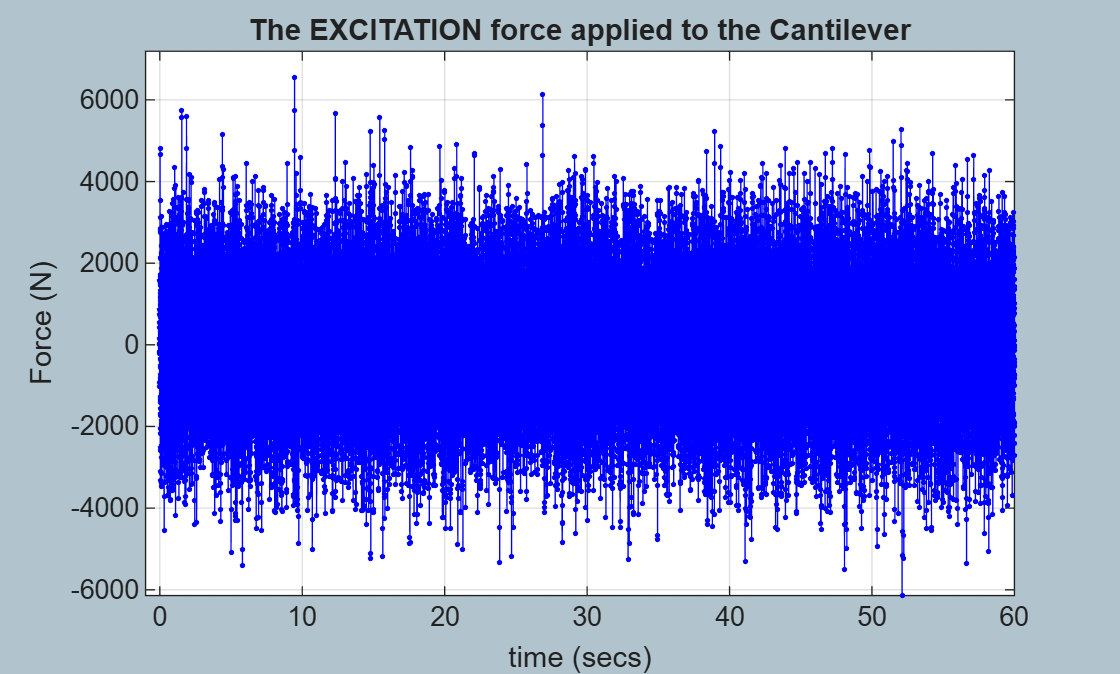


figure;
    plot(THE_EXCITER.t, THE_EXCITER.f, ".b-");
        xlabel("time (secs)"); ylabel("Force (N)");  grid("on");
        title("The EXCITATION force applied to the Cantilever");
        xlim([-1, max(THE_EXCITER.t)]);  ylim([min(THE_EXCITER.f), 1.1*max(THE_EXCITER.f)]);

Solve the ODEs

-      $\dot{Z} = A . Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

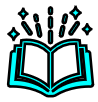 **DOC**:   see [`odeset()`](matlab: doc odeset) , [`ode15s()`](matlab: doc ode15s)

MY_SYSTEM = @(t, z) A_mat*z + [inv_M*THE_EXCITER.Fh(t); zeros(n,1)];

% Define some ODE solver settings
t_span     = THE_EXCITER.t;  % 0:THE_DT:10;
my_options = odeset('RelTol', 1e-4, 'AbsTol', 1e-4, "MaxStep",THE_EXCITER.dt);

  **ATTENTION:**  This  may take a few minutes  (or 4-5 minutes) to execute

% use ODE15s to numerically solve our system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode15s(MY_SYSTEM, t_span, z_init, my_options);

**NOTE:**

- The `Z` matrix has dimensions   $\left(\mathrm{Number}\;\mathrm{of}\;\;\mathrm{TIME}\;\mathrm{STEPS}\right)\;\;\times \;\left(\mathrm{Number}\;\mathrm{of}\;\mathrm{active}\;\mathrm{DOF}\right)\;$

## Extract and Plot the time varying VERTICAL displacements

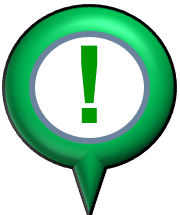 **NOTE:**  The `Z` matrix has columns corresponding to ALL of our dof , i.e.:

-  
$$X^T =  \pmatrix{
u_2 ,  &
v_2 , &
\theta_2, &
u_3 ,  &
v_3 , &
\theta_3, &
u_4 ,  &
v_4 , &
\theta_4, &
u_5 ,  &
v_5 , &
\theta_5,  \quad .... \quad etc
}$$


- 
$$Z\;=\;\left\lbrack \begin{array}{c}
\;\dot{X} \;\\
X
\end{array}\right\rbrack$$


- But we're only interested in the transverse **positional** dof, ie:  $v_2 \;,v_3 \;,v_4 \;,v_5 \;,\ldotp \ldotp \ldotp \ldotp$

- Within `X` these transverse positional dof are at locations  `(2 + 3*k) `for k=0,1,2 ..

X_MAT  =     Z( :, (n+1):end);  % ALL POSITIONAL dof
V_MAT  = X_MAT( :, 2:3:end  );  % Transverse POSITIONAL dof only

v_lims = [min(V_MAT,[], "all"),  max(V_MAT,[], "all")];

### Plot the response - Part 1

Let's look at the transverse displacement of the **TIP** of the cantilever 

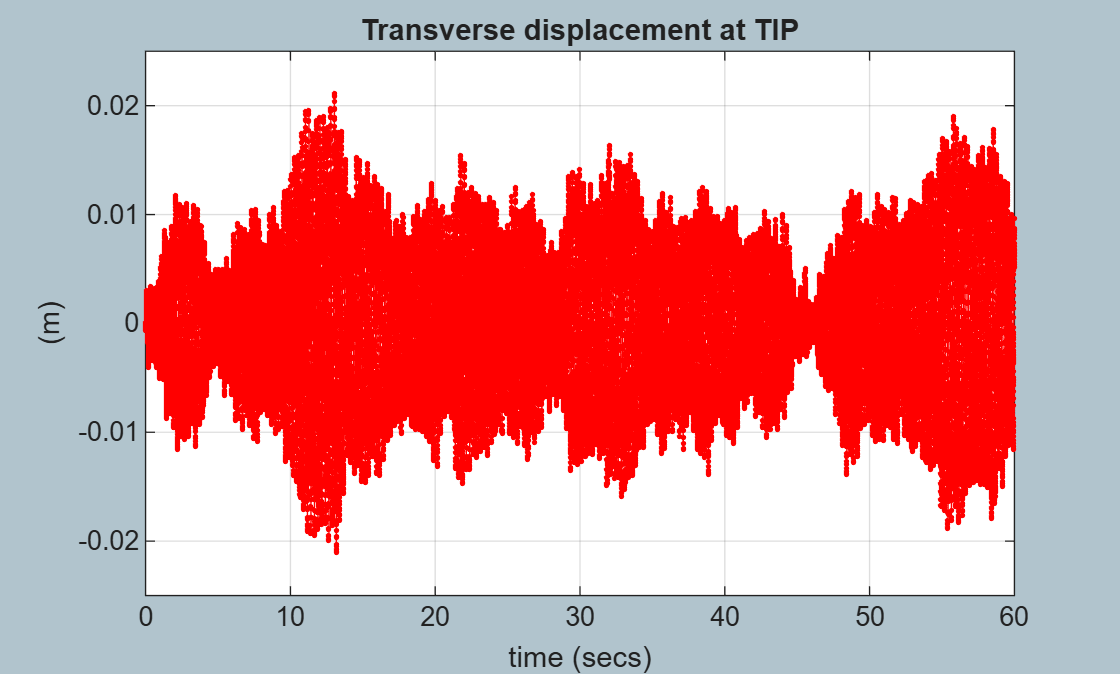

figure;
    plot(T, V_MAT(:, end), ".r-");
        xlabel("time (secs)"); ylabel("(m)");  grid("on");
        title("Transverse displacement at TIP")        

### Plot the response - PART 2

Note, if we plot the transverse response at EVERY timestep ... it will take a long time to produce the plot. So ? - So consider plotting the response to say every 5th time step

% T_step_to_show = 5;
% 
% figure
% for kk=1:T_step_to_show:size(V_MAT,1)
%     % extract the response for every transverse dof at this time
%     v = V_MAT(kk,:);
% 
%     % add a ZERO to the beginning to represent ZERO displacement 
%     % at the boundary dof
%     v = [0, v];
% 
%     % create a vector of the HORIZONTAL positions of the nodes
%     x = [0:NUM_ELES]*L;
% 
%     % Plot the stuff
%     plot(x, v,"-ro");
%         ylim(v_lims)
%         grid on
%         xlabel("x (m)")
%      % update screen
%     drawnow limitrate
% end
% title("Time varying Vertical response of Cantilever")

## Store results in a table and write to an EXCEL file

 **ATTENTION: **We'll write the results to an EXCEL file named `tmp_Cantilver_.xlsx`.  IFFF you wish to continue analyzing this data you should **manually rename** the EXCEL file to one of the following:

- `MEAS_CANTIL_02_hammer_T_F_v2_to_v21.xlsx`

- `MEAS_CANTIL_01_shaker_T_F_v2_to_v21.xlsx `

RESULTS_TABLE = table();

Add columns of time $t$ and the applied force $F\left(t\right)$

RESULTS_TABLE.t = T;
RESULTS_TABLE.F = THE_EXCITER.f(:);

Add columns for the transverse displacement dofs $v_k$

for kk=1:length(v_dof_labels)
    label_str = v_dof_labels(kk);

    RESULTS_TABLE.(label_str) = V_MAT(:,kk);
end

Delete EXCEL file if it exists and then create a NEW one

tmp_filename = "tmp_Cantilver_.xlsx";

delete(tmp_filename);

writetable(RESULTS_TABLE, tmp_filename)

# **Local Subfunctions ONLY beyond this point**

Define the Local Element Mass and Stiffness matrices

#   

The local stiffness matrix for the frame element can be defined as:   $[\thinspace ^LK_{ele} \thinspace] = F(A,E,I,L)$, where:

- A : is the cross sectional area  $\left(m^2 \right)$

- E : is Young's modulus $\left(N/m^2 \right)$

- I : is the 2nd moment of Area $\left(m^4 \right)$

- L : is the element's length $\left(m\right)$

Reference:

-    Rao, S., "Mechanical Vibrations, 2nd Edition", Addison Wesley, 1990

function [K_ele, M_ele] = LOC_get_Kele_Mele_LOCAL(A, E, I, L, density)

    K_ele = ...
     [  %   u1             v1            th1           u2              v2            th2        
       ( A*E/L  ), (       0   ), (       0   ),   (-A*E/L  ), (       0   ), (       0   );
       (    0   ), ( 12*E*I/L^3), (  6*E*I/L^2),   (    0   ), (-12*E*I/L^3), (  6*E*I/L^2);
       (    0   ), (  6*E*I/L^2), (  4*E*I/L  ),   (    0   ), ( -6*E*I/L^2), (  2*E*I/L  );
       (-A*E/L  ), (       0   ), (       0   ),   ( A*E/L  ), (       0   ), (       0   );
       (    0   ), (-12*E*I/L^3), ( -6*E*I/L^2),   (    0   ), ( 12*E*I/L^3), ( -6*E*I/L^2);
       (    0   ), (  6*E*I/L^2), (  2*E*I/L  ),   (    0   ), ( -6*E*I/L^2), (  4*E*I/L  );
      ];
    
    M_ele = (density*A*L/420) * ...
     [  %   u1             v1            th1           u2              v2            th2
         (140),          (0),           (0),        (70),            (0),           (0);
           (0),      (  156),        (22*L),         (0),           (54),       (-13*L);   
           (0),       (22*L),       (4*L^2),         (0),         (13*L),      (-3*L^2);
          (70),          (0),           (0),       (140),            (0),           (0);
           (0),         (54),        (13*L),         (0),          (156),       (-22*L); 
           (0),      (-13*L),      (-3*L^2),         (0),        (-22*L),       (4*L^2);
     ] ;  

end

Define an excitation function

function F_col = LOC_F_exciter(t, n, exciter)

    some_F_scalar = interp1(exciter.t,exciter.f,t); 

    F_col = zeros(n,1);

    F_col(exciter.DOF_ID) = some_F_scalar;
   %fprintf("\n t= %f", t)
end